# Autorepression system with Hill function input

Max Wang (ID:2018012386) [wangmx18@mails.tsinghua.edu.cn](http://wangmx18@mails.tsinghua.edu.cn)

Oct 26, 2021

## 1. model construction

The production rate follows** Hill** function:


$$$Hill(x)=\frac{1}{1+(x/k_d)^n}$$$


According to the following figure, we can see that the higher the $\frac{x}{k_d}$ ratio, the lower the production rate is.

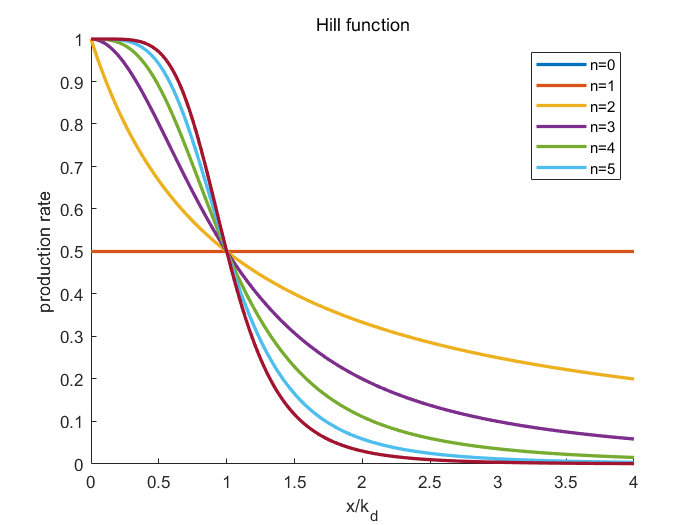

x=[0:0.01:4];
y = zeros(6,size(x,2));
figure(1)
hold off
for i = 0:5
    y(i+1,:)=Hill(x,1,i);
    hold on
    plot(x,y(i+1,:),'LineWidth',2)
    hold off
end
xlabel('x/k_d')
ylabel('production rate')
legend('n=0','n=1','n=2','n=3','n=4','n=5')
title('Hill function')

% Hill(1,2,2)

Assume that the degradation rate is $\alpha x$. Then we have:


$$\frac{dx}{dt}=\beta*Hill(x)-\alpha*x$$


in which $\alpha$ is the degradation rate, and $\beta$ is maximal production rate.

The following graph shows the simulation result for two systems with only initial concentration difference.

global alpha; global beta; global k_d; global n;
alpha = 1; beta = 20000; k_d = 0.1; n = 2;
global alpha_0; global k_0;
alpha_0 = alpha; 
s_stable = (beta*k_d^n/alpha)^(1/(n+1))

s_stable = 5.8480

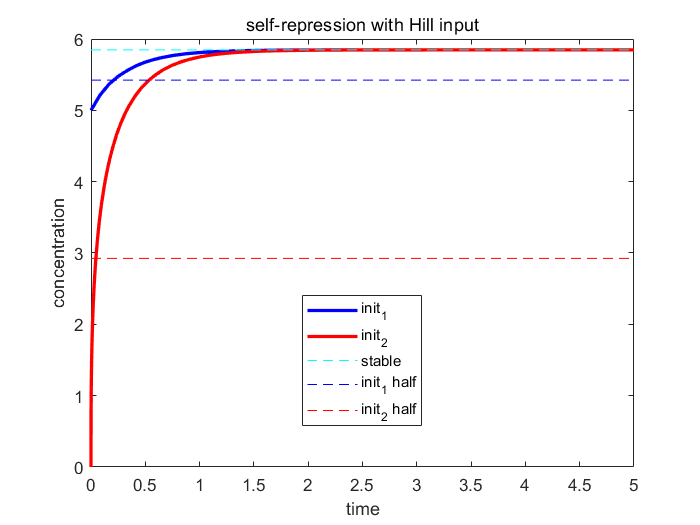

k_0 = alpha_0*s_stable;

s0_1=[5];
s0_2=[0];
tspan = [0,5];

[t1,s1] = ode45(@self_rpr, tspan, s0_1);
[t2,s2] = ode45(@self_rpr, tspan, s0_2);


figure(2);
plot(t1,s1,'LineWidth',2,"Color",'b');
hold on
plot(t2,s2,'LineWidth',2,"Color",'r')
plot(tspan,[s_stable, s_stable],'c--')
plot(tspan,[(s0_1+s_stable)/2,(s0_1+s_stable)/2],'b--')
plot(tspan,[(s0_2+s_stable)/2,(s0_2+s_stable)/2],'r--')
hold off
ylim([0 6])
xlabel('time')
ylabel('concentration')
legend('init_1','init_2','stable','init_1 half','init_2 half','Location',"best")
title('self-repression with Hill input')

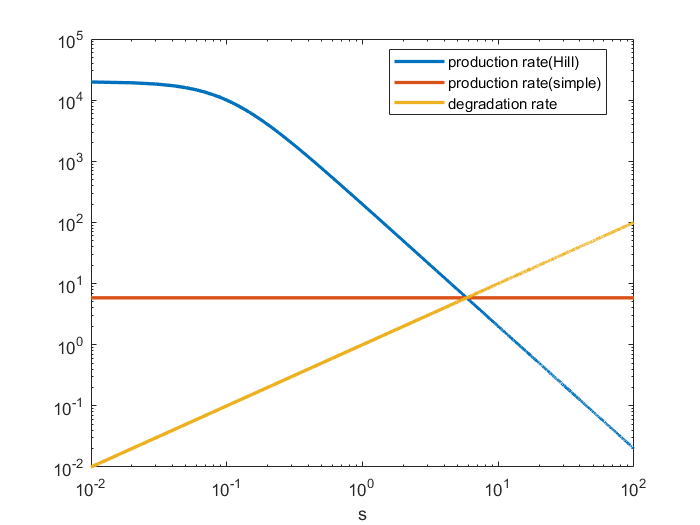

figure(3)
x=[0:0.1:1000];
% semilogy(x*k_d,beta*Hill(x*k_d,k_d,n))
% hold on
% semilogy([0,max(x)*k_d],[k_0,k_0])
% semilogy(x*k_d, alpha*x*k_d)
% hold off

loglog(x*k_d,beta*Hill(x*k_d,k_d,n),"LineWidth",2)
hold on
loglog([0.01,max(x)*k_d],[k_0,k_0],"LineWidth",2)
loglog(x*k_d, alpha*x*k_d,"LineWidth",2)
hold off
legend('production rate(Hill)','production rate(simple)','degradation rate','Location',"best")
xlabel('s')

We can find that the response time of the two systems are the same (appr. 0.67).

By $x>>k_d$ approximation,$\frac{dx}{dt}=\frac{\beta*{k_d}^n}{x^n}-\alpha*x$.

response time approximately equals to $T_{1/2}^{self-rpr}=\frac{1}{(n+1)\alpha}ln(\frac{2^{n+1}+1}{2^{n+1}})$ .

Here the calculated result is 

T_half=1/(n+1)/alpha*log(2^(n+1)/(2^(n+1)-1))

T_half = 0.0445

## 2. comparisions with non-autoregulated circuits

Non-autoregulated circuits: 

production rate is constant $v_0$, degredation rate is $\alpha_0 *x$.

Thus we have$\frac{dx}{dt}=k_0-\alpha_0*x$.

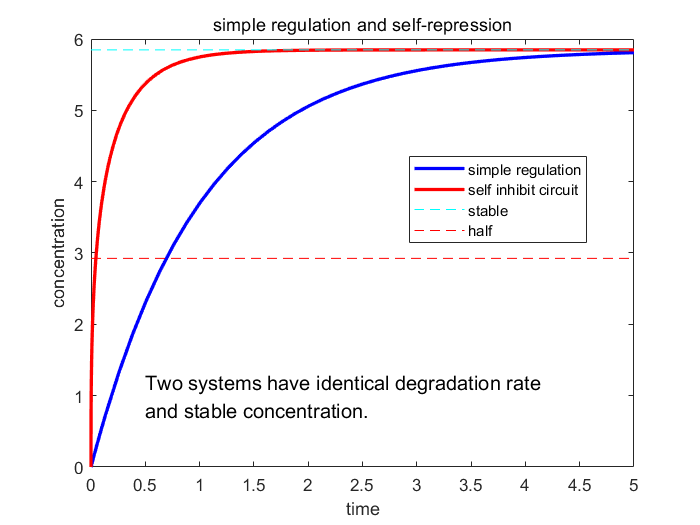

global alpha_0; global k_0;
alpha_0 = 1; 
k_0 = alpha_0*s_stable;

[t3,s3]=ode45(@simple,tspan,s0_2);

figure(4);
plot(t3,s3,'LineWidth',2,"Color",'b');
hold on
plot(t2,s2,'LineWidth',2,"Color",'r')
plot(tspan,[s_stable, s_stable],'c--')
plot(tspan,[(s0_2+s_stable)/2,(s0_2+s_stable)/2],'r--')
hold off
ylim([0 6])
xlabel('time')
ylabel('concentration')
str={'Two systems have identical degradation rate', 'and stable concentration.'};
text(0.5,1,str,"FontSize",12)
legend('simple regulation','self inhibit circuit','stable','half','Location',"best")
title('simple regulation and self-repression')

For simple regulaton, the response time is


$$T_{1/2}^{simple}=\frac{ln2}{\alpha_0}$$


Thus, $T_{1/2}^{simple}\approx T_{1/2}^{self-rpr}*(n+1)$, as long as the two systems share the same degradation rate and stable concentration.

function z=Hill(x,k_d,n)
kd = ones(size(x))*k_d;
z =zeros(size(x));
z = 1./(1+(x./kd).^n);
end

function ds = self_rpr(t,s)
% This function is the model for self repression;
% alpha: degradation rate; beta:maximal production rate;
global alpha; global beta; global k_d; global n;
ds = beta*Hill(s, k_d, n)-alpha*s;
end

function ds = simple(t,s)
% This function is the model for simple regulation;
% alpha_0: degradation rate; k_0:production rate;
global alpha_0; global k_0;
ds = k_0-alpha_0*s;
end